% Homework 3
% EE 261
% Summer 2020
% Noor Fakih
clear all; close all;

# Voice Scrambling/Descrambling

load scramble.mat % gives us fs, nbits, scram

### Part A

### Do you need to know the exact pre-determined key in order to get the original signal?

No, you don't! There are 8 subbands, meaning there are 8! different combinations but that does not mean that you actually have to know the key or try all 8! combos to get the original signal. The human voice is contined to the low freq band which would be the first four subbands, A B C D. The higher frequency ones, E F G H, are not really relevant and can be placed in the wrong order without too signficantly changing the original signal's message. By plotting the signal in the frequency domain and using the information stated before, we can identify the order of the low freq bands and get an answer. And if we do need to guess, there are 4! or 24 options which is significantly less than 8!.

### Part B

### Descramble the Signal

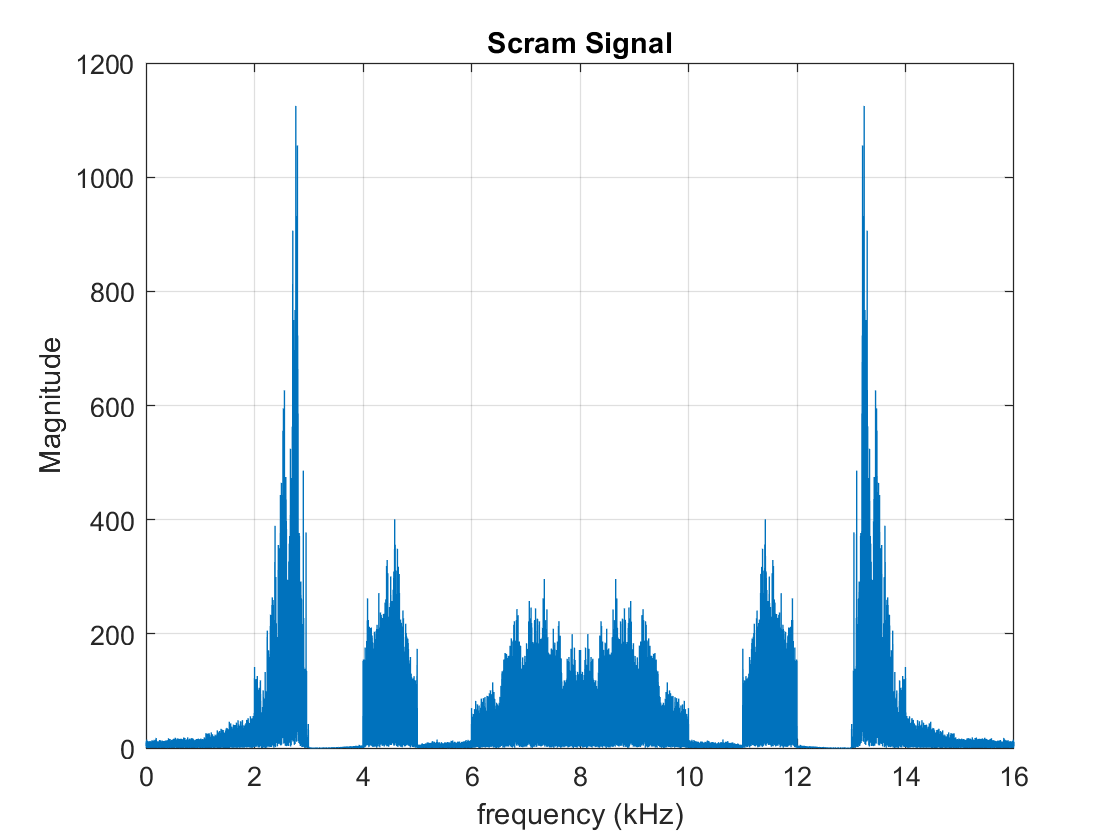

% plot original signal
N = length(scram);
scram_fft = fft(scram);
freq = (0:(N-1))'/N*fs/1000;
plot(freq, abs(fftshift(scram_fft)));
title('Scram Signal');
xlabel('frequency (kHz)'); ylabel('Magnitude');
grid on;

% plot signal in a different way to see bins better...
N = length(scram);
scram_fft = fft(scram);
freq = (0:(N-1))'/N*fs/1000;
% Note: don't use fftshift and only display half the signal
plot(freq(1:N/2), abs(scram_fft(1:N/2)));

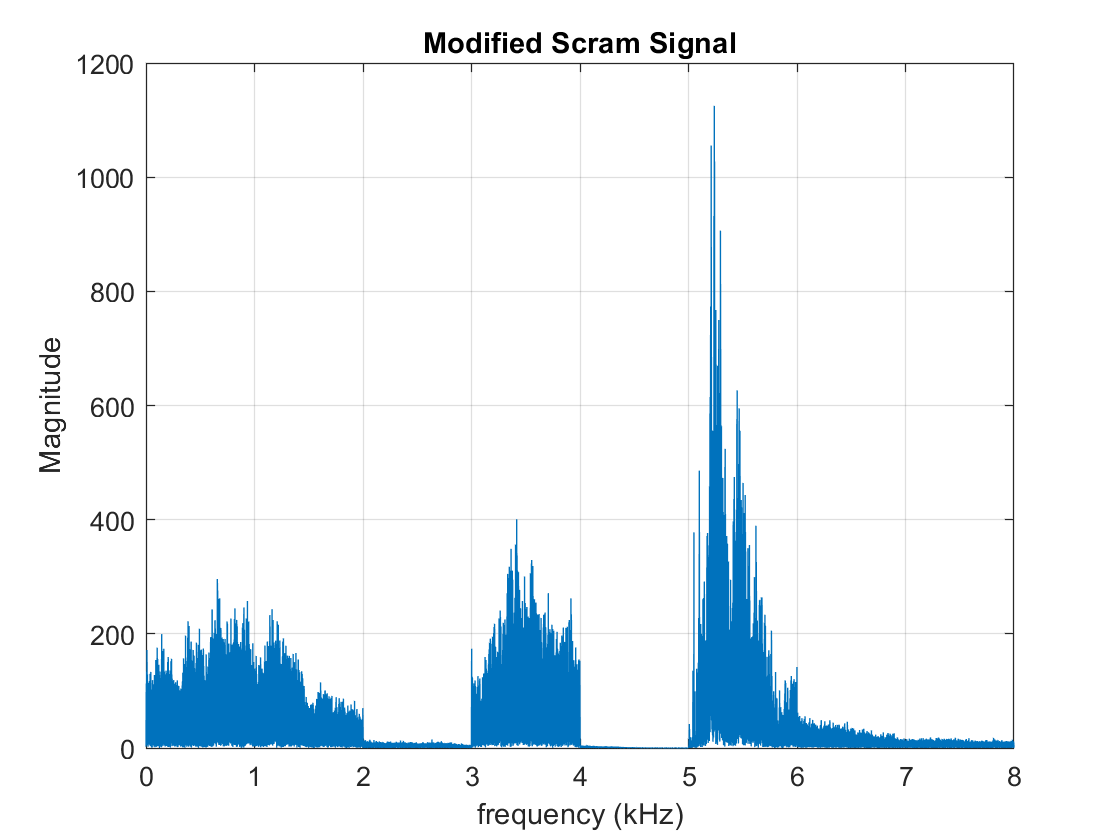

title('Modified Scram Signal');
xlabel('frequency (kHz)'); ylabel('Magnitude');
grid on;

% By using the plot of the modified scrambled signal, identify correct band order
% C D G B H A E F

% correct indexing
if (mod(N,2) == 1)
    maxFreq = uint32((N+1)/2);
    F = scram_fft(floor(maxFreq/8*7)+1:maxFreq);
else
    maxFreq = N/2 + 1;
    F = scram_fft(floor(maxFreq/8*7)+1:maxFreq-1);
end

% Assign Bands to proper Bins
C = scram_fft(2:floor(maxFreq/8));
D = scram_fft(floor(maxFreq/8)+1:floor(maxFreq/8*2));
G = scram_fft(floor(maxFreq/8*2)+1:floor(maxFreq/8*3));
B = scram_fft(floor(maxFreq/8*3)+1:floor(maxFreq/8*4));
H = scram_fft(floor(maxFreq/8*4)+1:floor(maxFreq/8*5));
A = scram_fft(floor(maxFreq/8*5)+1:floor(maxFreq/8*6));
E = scram_fft(floor(maxFreq/8*6)+1:floor(maxFreq/8*7));

% Order Bands correctly to recover the signal
lowFreq = [A; B; C; D];
revLowFreq = flipud(conj(lowFreq));
highFreq = [G; H; E; F];
revHighFreq = flipud(conj(highFreq));
new_fft = [ scram_fft(1); lowFreq; highFreq; revHighFreq; revLowFreq];

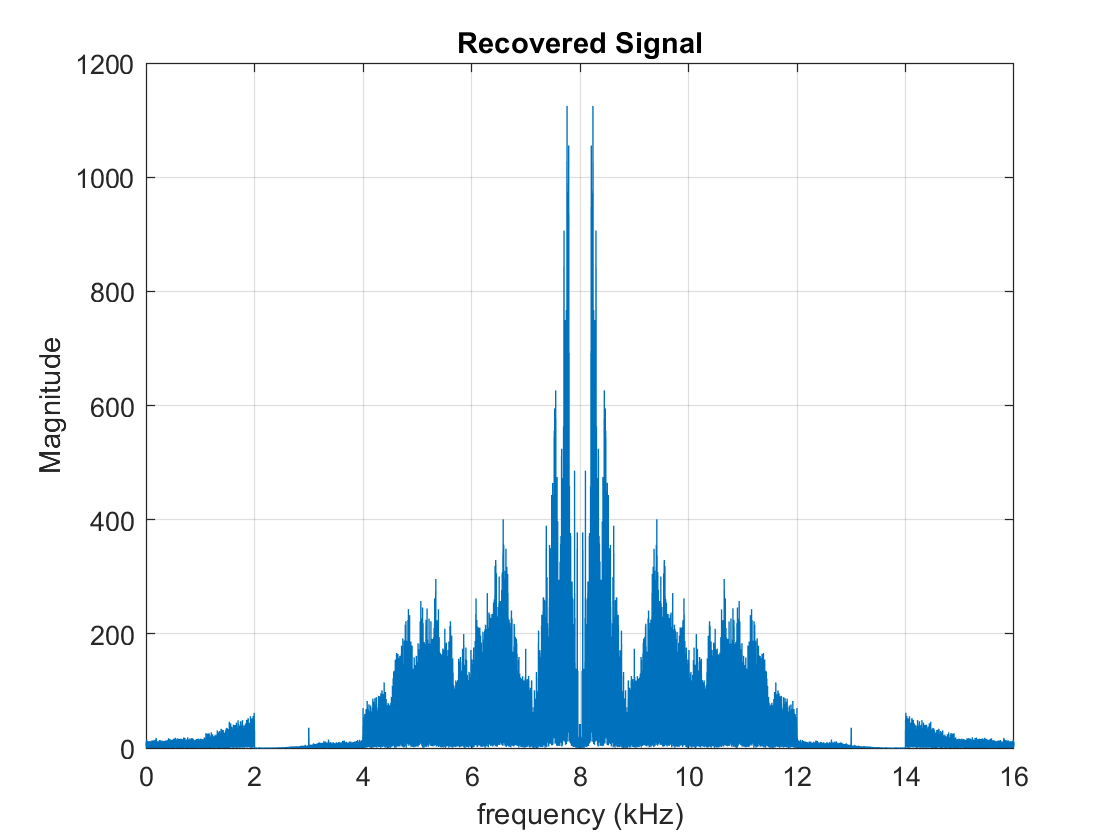

% plot new recovered signal
plot(freq, fftshift(abs(new_fft)));
title('Recovered Signal');
xlabel('frequency (kHz)'); ylabel('Magnitude');
grid on;

% Convert the new signal back to the time domain
recovered_signal = real(ifft(new_fft));
sound(recovered_signal, fs);

#### Transcription

We shall fight on the grounds, we shall fight on the seas and oceans, we shall fight with growing strength and confidence... we shall never surrender! 

### Part C

### Is this a good encryption scheme? If so, give a brief explanation of why. If not, explain its deficiencies and suggest a way to improve its resistance to attacks.

This is a horrible encryption scheme. With some guidance and an FT class, I was able to crack it. Also, to hear the core message you only need the 4 low freq bands to be in order. That means there are only 24 different combos to try, which isn't that many or would take that long to test out each case. One way the security could be enhanced is by decreasing the range of the bands so that there would be more subbands. You potentially may stilll not have too hard of a time cracking a signal with more scrambled subbands since you could employ a similiar method and just look at the FT again, so maybe this is just not a good encryption method.